# Euler-Bernoulli beam (steady-state, 1d)

**Notes**: 

Literature: mini switches, magnetic resonator, physical measures

Lee's paper, MIT wave guide

$u_{xx}$ modified plot

## Mixed formulation for the simply-supported beam

### DE parameters

% from Lee, D. Wei's paper
L = 1; % length of the beam
rho = 1; % density of the material
E = 1; % young's modulus
sigma_max = .13;
D = -5*(E^2)/(4*sigma_max); % nonlinear elastic modulus
I1 = 1; % moment of inertia
I2 = 0.02; % moment of inertia
% F = 10e6; % external force
F = -2;

f = @(x) F;
hfun = @(x) abs(x).*x;

### FEM parameters

NEL = 200;
gauss_points_num = 3;

master = [0 1];

Nb = 2;
% linear elements
coeffs = [ 0, 1; 
           1,-1];

% basis functions on the master element
N = basis_functions(coeffs);
d1_N = basis_derivatives(coeffs, 1);

% global nodes
xs = linspace(0,L,NEL+1);

% mesh sizes
hs = zeros(NEL,1);
for i=1:NEL
    hs(i) = xs(i+1) - xs(i);
end

### Matrix assembly

[K,M,Fvec] = assemble_system(NEL,Nb,xs,hs,master,N,d1_N,f,gauss_points_num);

% for the linear problem
Klen = length(K);
Flin = [Fvec;zeros(Klen,1)];
Klin = [-E*I1*K zeros(Klen,Klen); M K];

### Solver prep

func = @(x) -E*I1*K*x - D*I2*K*hfun(x) - Fvec;
options = optimset('Display','off');

### Solver routines

vs = fsolve(func, ones(length(K),1), options);
us = K\(-M*vs);

soln = Klin\Flin;
vslin = soln(1:Klen);
uslin = soln(Klen+1:end);

### Solution vectors

vs_full = [0;vs;0]; vslin_full = [0;vslin;0];
us_full = [0;us;0]; uslin_full = [0;uslin;0];

## Plotting

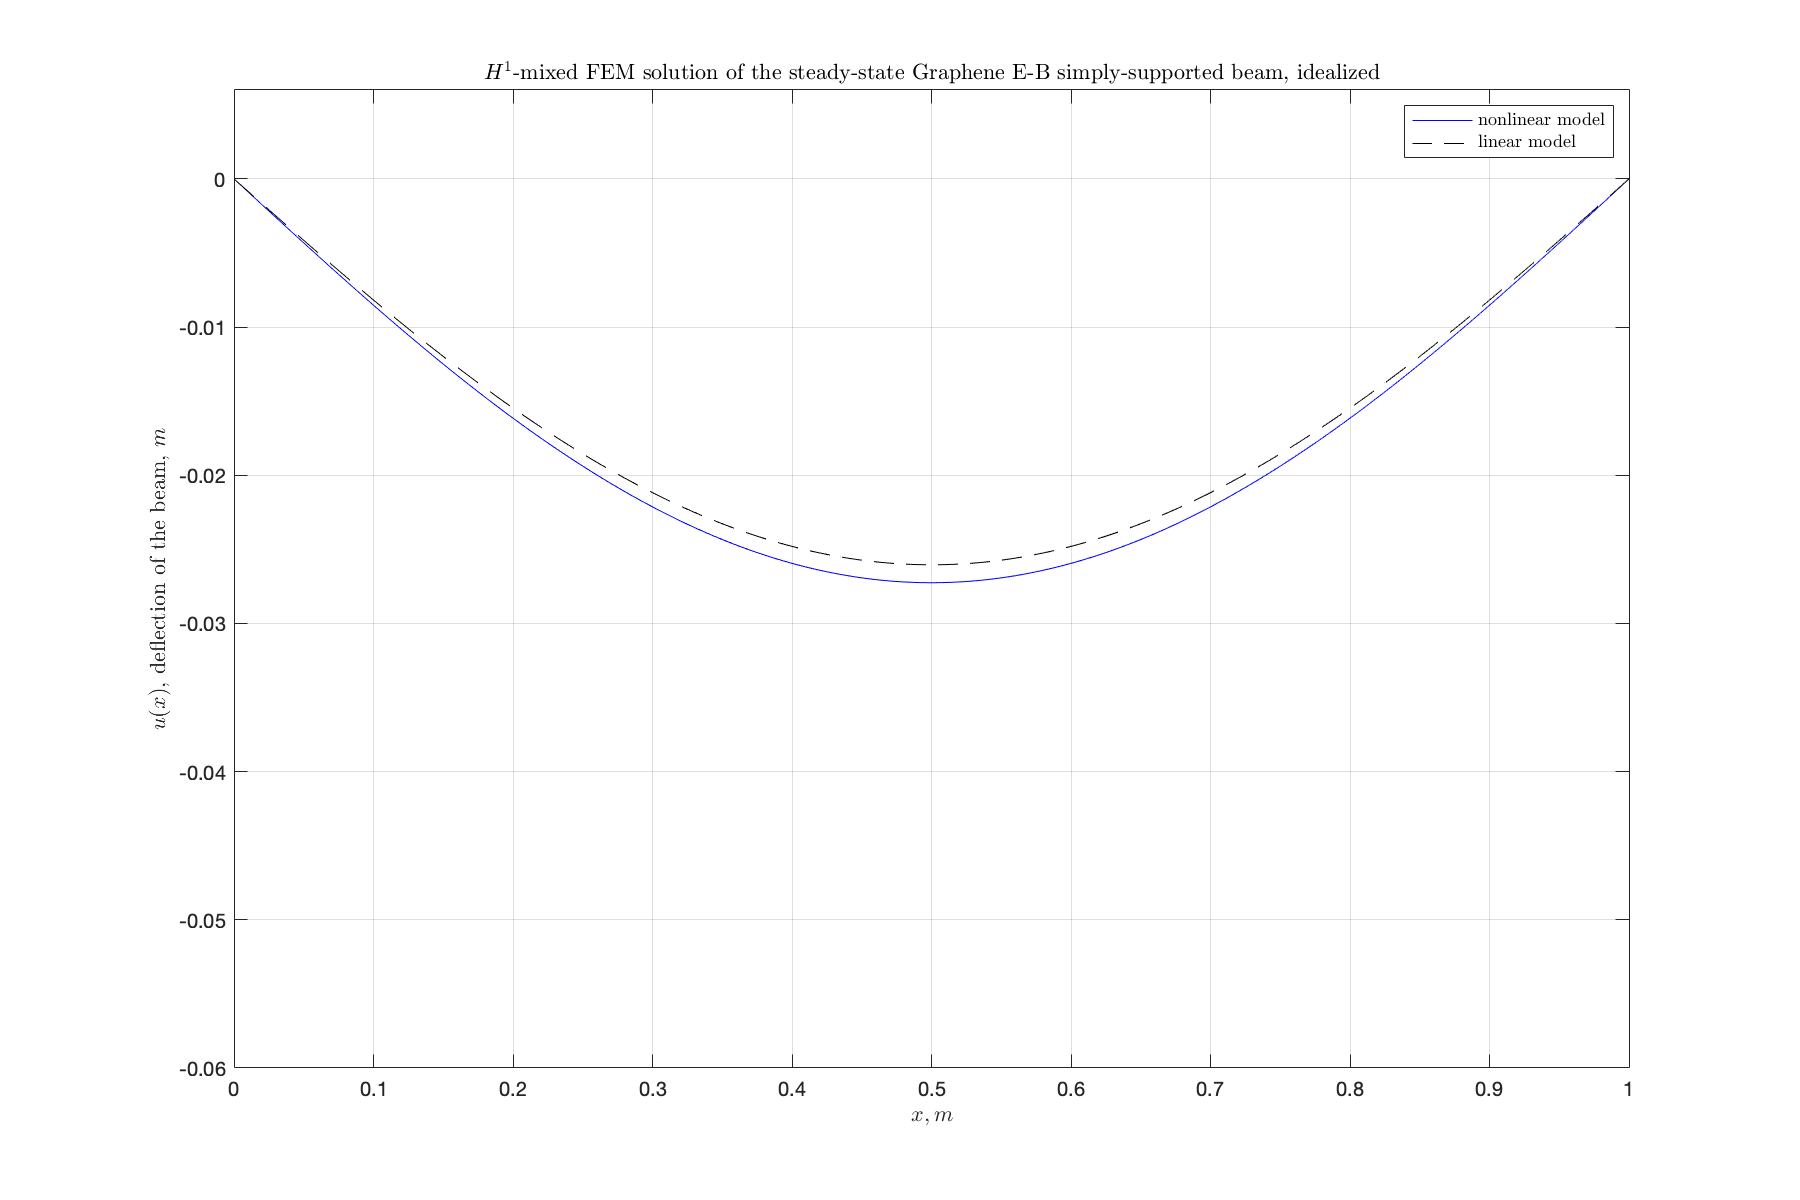

clf
ampl = 6e-2;
figure('Position', [10 10 900 600])
% figure
% plot(xs,us_full,'b-', xs,uslin_full,'k--',xs, E*I1*vs_full + D*I2*hfun(vs_full)'*vs_full,'r--', xs,vslin_full,'m--') 
% plot(xs,us_full,'b-', xs,uslin_full,'k--', xs, vs_full,'r--', xs,vslin_full,'m--')
plot(xs,us_full,'b-', xs,uslin_full,'k--')
grid on
xlim([0 L])
ylim([-ampl,ampl/10])

title("$H^1$-mixed FEM solution of the steady-state Graphene E-B simply-supported beam, idealized", "Interpreter","latex")

xlabel('$x, m$', "Interpreter","latex")
ylabel('$u(x)$, deflection of the beam, $m$', "Interpreter","latex")

leg = legend('nonlinear model',"linear model");    
set(leg,'Interpreter','latex');
legend("Location","northeast")

hold off

## Appendix

### FEM tools

function [Kmat,Mmat,Fvec] = assemble_system(NEL,Nb,xs,hs,master,N,d1_N,f,gauss_points_num)
    Kl = zeros(Nb,Nb,NEL);
    Ml = zeros(Nb,Nb,NEL);
    Fl = zeros(Nb, 1,NEL);
    for k=1:NEL
        for i=1:Nb
            for j=1:Nb
                Kl(i,j,k) = 1 / (hs(k)) * gauss(@(x) d1_N(i,x) * d1_N(j,x), master(1), master(2), gauss_points_num);
                Ml(i,j,k) =      hs(k)  * gauss(@(x)    N(i,x) *    N(j,x), master(1), master(2), gauss_points_num);
            end
            % since f is defined globally, we need to apply change of variable to integrate it on the master element
            Fl(i,1,k) =          hs(k)  * gauss(@(x)    N(i,x) * f(xs(k)+hs(k)*x), master(1), master(2), gauss_points_num);
        end
    end
    
    % Global matrices and force term
    Kn = NEL+1;
    K = zeros(Kn,Kn); M = zeros(Kn,Kn);
    F = zeros(Kn,1);
    for i=1:NEL
        K(i:i+1,i:i+1) = K(i:i+1,i:i+1) + Kl(1:Nb,1:Nb,i);
        M(i:i+1,i:i+1) = M(i:i+1,i:i+1) + Ml(1:Nb,1:Nb,i);
        F(i:i+1,1) = F(i:i+1,1) + Fl(1:Nb,1,i);
    end
    
    Kmat = K(2:end-1,2:end-1);
    Mmat = M(2:end-1,2:end-1);
    Fvec = F(2:end-1);
end

### Polynomial tools

function basis = basis_functions(coefficient_matrix)
    mat_size = length(coefficient_matrix);
    basis = @(index, x) coefficient_matrix(index,1:mat_size)*(x.^(0:mat_size-1))';
end

function der_mat = derivative_matrix(basis_order, derivative_order)
    der_mat = zeros(basis_order, basis_order);
    for i=derivative_order+1:basis_order
        prod = 1;
        for j=1:derivative_order
            prod = prod*(i-j);
        end
        der_mat(i-derivative_order,i) = prod;
    end
    der_mat = sparse(der_mat');
end

function res = basis_derivatives(coefficient_matrix, order)
    der_mat = derivative_matrix(length(coefficient_matrix), order);
    res = basis_functions(coefficient_matrix*der_mat);
end

function res = gauss(fun, a, b, order)
    [x,w] = lgwt(order,a,b);
    f = arrayfun(fun,x);
    res = sum(f.*w);
end
